# matlab2word

## Описание библиотеки

Данная библиотека позволяет перенести ваши расчеты в документ шаблона в MS Word. Это полезно, когда у вас есть файл отчета с определенным форматированием и требующий расчета некоторых значений.

MS Word имеет отличные возможности для форматирования текстов, но встроенный язык VBA скриптов слабо  неудобен для вычислений (особенно инженерных). MatLAB отлично подходит для расчетов и также имеет некоторый функционал для генерации отчета. Отчет через MatLAB генерируется с помощью кода, что не совсем удобно для форматирования этого отчета. Моя библиотека позволяет объединить отформатированный в MS Word документ и расчеты из MatLAB в один файл отчета.

Для работы библиотеки требуется версия **MATLAB R2013b или новее**.

## Подготовка Word документа

Изначально в Word нужно изменить некоторые параметры. Для этого откройте меню ***Файл***-***Параметры***-***Центр управления безопасностью***-***Параметры центра управления безопасностью...***-***Параметры макросов*** и установите значение "*Отключить все макросы без уведомления*".Также возможно понадобится отключить автосохранение.

В файле Word вставьте id строки (как показано на рисунке ниже) которые будут заменены на рассчитанные значения. Заключите id строки в треугольные скобки `<>`. Учтите, что в поле ввода формул id строка должна быть без *курсивного* начертания, это важно чтобы найти эту строку в поле формул.

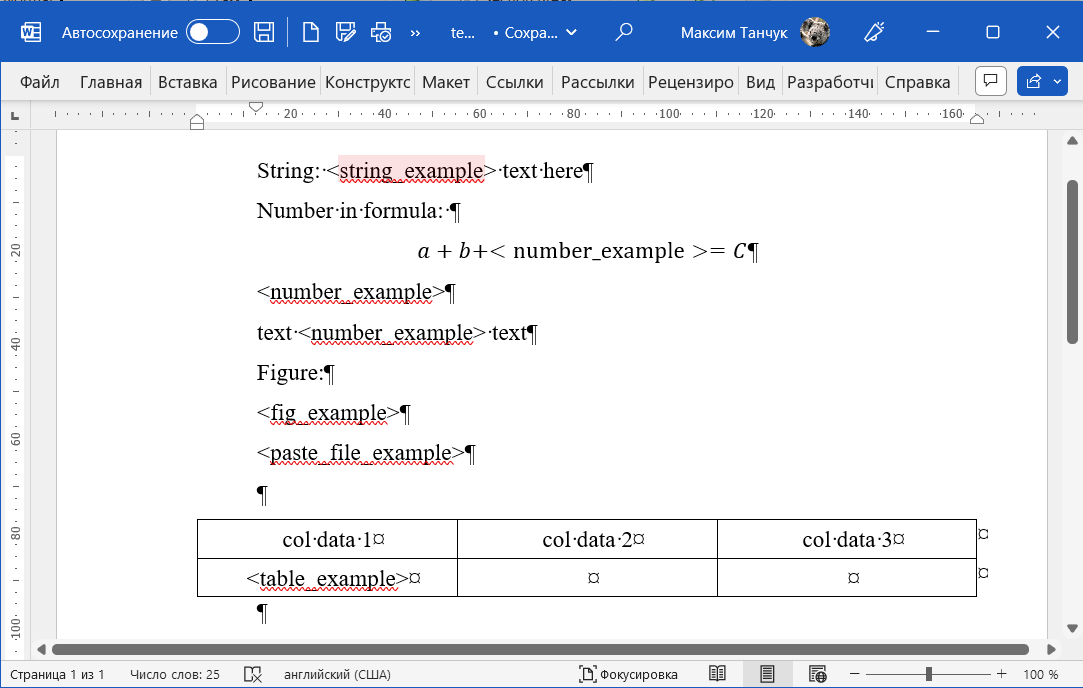

После создания вашего шаблона отчета сохраните его в формате **.docx** и полностью закройте приложение Word включая другие открытые документы.

## Пример расчета

clc, clear, close all;

Пусть ваш расчет выглядит следующим образом.

test_string = 'Hello';
test_num = 38600000000000000000-0.000000000013i;
% Create test figure
x = (-4*pi):(8*pi/1000):(4*pi);
f_x_sin_x = sin(x);
fig1 = figure(1); % Here you need to store the figure handler
plot(x, f_x_sin_x);

Здесь есть обычная строка, число и фигура с графиком. Давайте перенесем их в Word.

## Перенос в Word

Сперва создайте объект вашего документа Word для доступа с нему.

% Create an instance of matlab2word object and get access to Word file
% m2w = matlab2word();

Эта команда при выполнении спросит вас выбрать файл шаблона. Также можно сразу задать имя шаблона в аргументе функции `matlab2word` function следующим образом:

m2w = matlab2word('template.docx');

По умолчанию MatLAB использует *точку* в качестве десятичного разделителя. Переключить на *запятую* можно командой:

m2w.SetDecimalSeparator(',');

По умолчанию MatLAB использует *i* в качестве индикатора мнимой части комплексного числа. Переключить на *j* можно командой:

m2w.SetImaginaryUnit('j');

Дальше просто замените ваши id строки рассчитанными значениями c помощью метода `Replace`.

m2w.Replace('string_example', test_string);
m2w.Replace('number_example', test_num);
m2w.Replace('fig_example', fig1);

Метод замены принимает 2 аргумента, один из которых является id строкой из документа шаблона, второй - переменная MatLAB. Функции замены могут выполняться некоторое время.

### Замена данными из другого файла

В библиотеке имеется возможность использовать данные для замены не только из MATLAB, но также из других файлов. Для этого используйте метод `PasteFile` с двумя аргументами (1 - id строка для замены; 2 - имя файла, который будет вставлен в ваш файл вместо id строки).

m2w.PasteFile('paste_file_example', 'template1.docx');
m2w.Replace('pasted_file_insert_test', 'Another text');

### Замена табличных данных

С помощью библиотеки можно заменить данные в таблице, количество строк которой заранее неизвестно. Таблица может быть задана в MATLAB с помощью двумерного массива или с помощью табличного типа. Основным требованием для корректной замены является соответствие количества столбцов в таблице шаблоне и в переменной MATLAB.

t1 = [1, 2, 3; 4, 5, 6];
t1 = table([1; 4], ['ab'; 'cd'], [3+5i; -67i]);

Замена выполняется следующей командой:

m2w.PasteTable('table_example', t1);

## Сохранение файла

В конце вам нужно сохранить полученный результат командой:

m2w.Save();

Эта команда автоматически сохранит файл с добавлением _out к имени вашего входного файла.

Если вам нужно задать другое имя выходного файла или изменить расположение его сохранения, вы можете задать имя явно таким же способом как это делается для входного файла.

% m2w.Save('output_file_name.docx');

Также вы можете выбрать выходной файл во время работы скрипта используя следующую команду:

% m2w.SaveManually();

(в таком случае откроется окно выбора места сохранения).